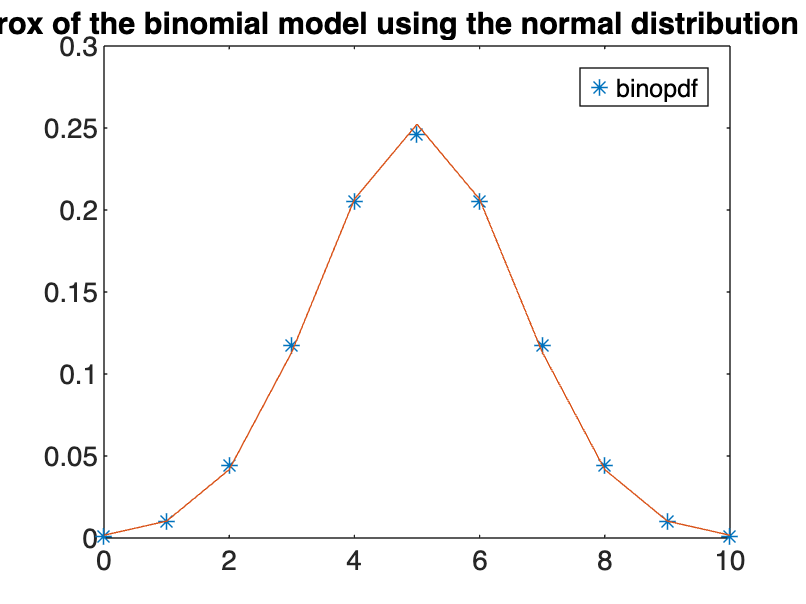

clc;
clear all;
p=input("prob of succes (0.05<=p<=0.95)=");
for n=1:10
    mu=n*p;
    sigma=sqrt(n*p*(1-p));
    k=0:n;
    px=binopdf(k,n,p);
    normpx=normpdf(k,mu,sigma);
    plot(k,px,'*');
    hold on;
    plot(k,normpx);
    hold off;
    title("Approx of the binomial model using the normal distribution model")
    legend("binopdf","normpdf");
    pause(0.5);
end